clf;
clear;

child = imread("../materials/child.tif");
load("../materials/H1&H2.mat");
[M, N] = size(child)

M = 812

N = 812

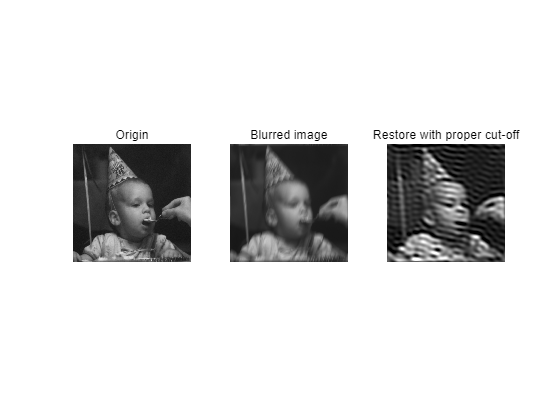


child_F = fftshift(fft2(im2double(im2gray(child))));
tmp = zeros(M,N);
cut_off = 20;
for i = 1:M
    for j = 1:N
        if sqrt((i-M/2)^2 + (j-N/2)^2)<cut_off
            tmp(i,j) = child_F(i,j)/H2(i,j);
        end
    end
end
child_D = real(ifft2(ifftshift(child_F.*H2)));
child2 = real(ifft2(ifftshift(tmp)));

subplot(1,3,1);
imshow(child);title("Origin");
subplot(1,3,2);
imshow(im2uint8(child_D));title("Blurred image");
subplot(1,3,3);
imshow(im2uint8(child2));title("Restore with proper cut-off");